%load data
load 'dataset/yalefaces.mat';

%reshape data
M = reshape(M, [1024, 2414]);

%find average vectors
M_avg = mean(M);

%find mean noralized M
X = M - M_avg;

%find C
C = X*X';

a) Singular values of x are the squareroot of the eigenvalues of C

Left singular values of X are equal to the eigenvectors of C.

b) Compute eigenvector/eigenvalue pairs of C. Comment if the eigenvalues are real and why. Plot log lambda_j against j.

[U,S,V] = svd(C);
s = svd(C)

s = 	1.0e+09 *

    3.2407
    1.0041
    0.4522
    0.2807
    0.1407
    0.1304
    0.0966
    0.0762
    0.0670
    0.0621


Yes the eigenvalues are real. Since C is symmetric, eigenvalues are real.

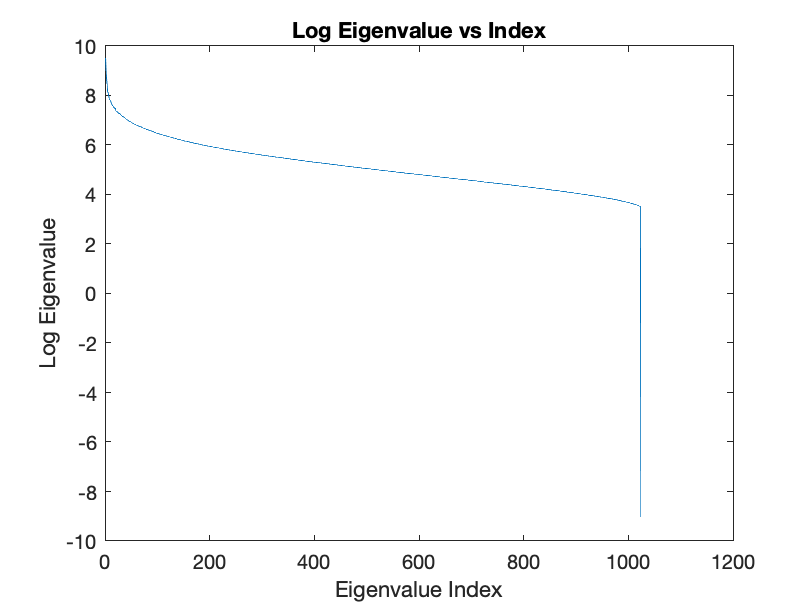

log_s = log10(s);
n = size(log_s,1);

figure;
plot(log_s);
xlabel('Eigenvalue Index');
ylabel('Log Eigenvalue');
title('Log Eigenvalue vs Index');

c) Reshape and plot first and last 10 vectors in v.

U = reshape(U, [32,32,1024]);

disp('First 10:')

First 10:


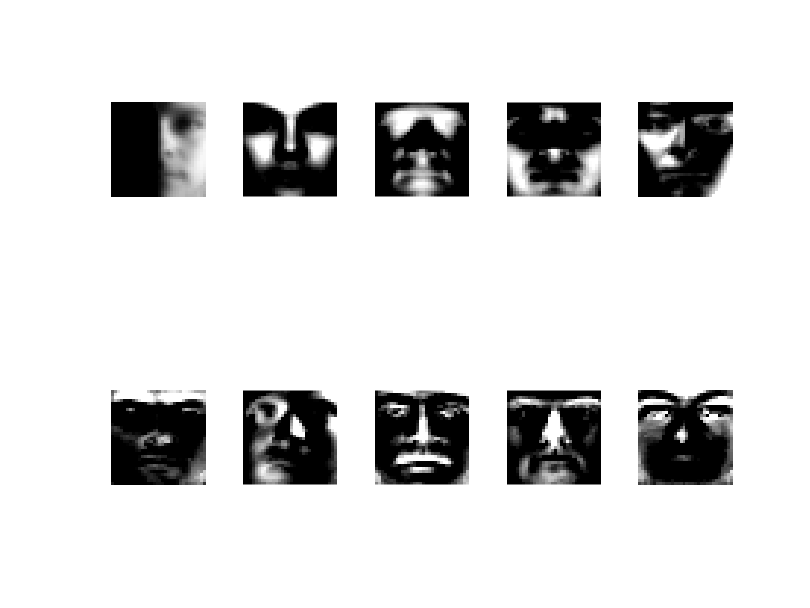

figure;
for i = 1:10
    subplot(2,5,i);
    imshow(U(:,:,i)*20);
end


figure;
disp('Last 10:')

Last 10:


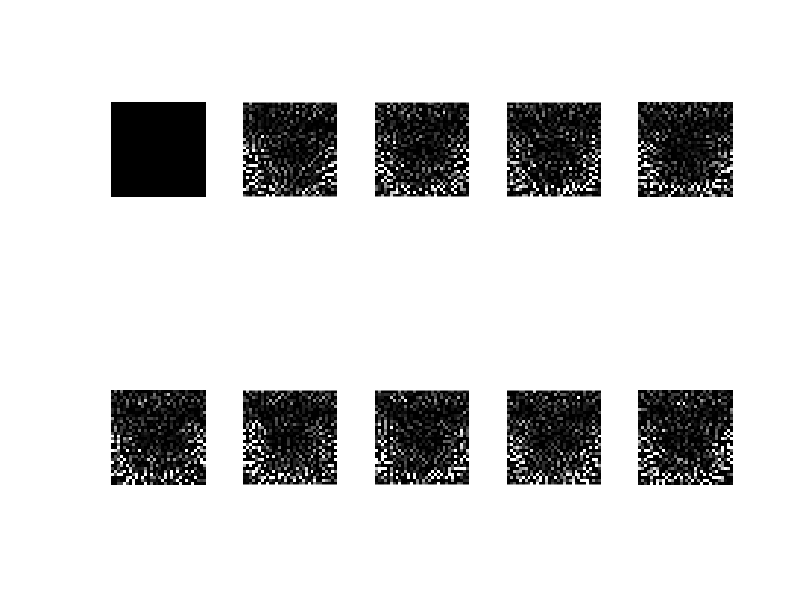

for i = 1015:1024
    subplot(2,5,1024+1-i);
    imshow(U(:,:,i)*20);
end


U = reshape(U, [1024,1024]);

Eigenvectors for the largest 10 resemble faces while the smallest 10 are incomprehensible. This demonstrates that there is more data in the first 10 eigenvectors.

d) Plot images 1, 1076, and 2043 using a varying number of basis vectors.

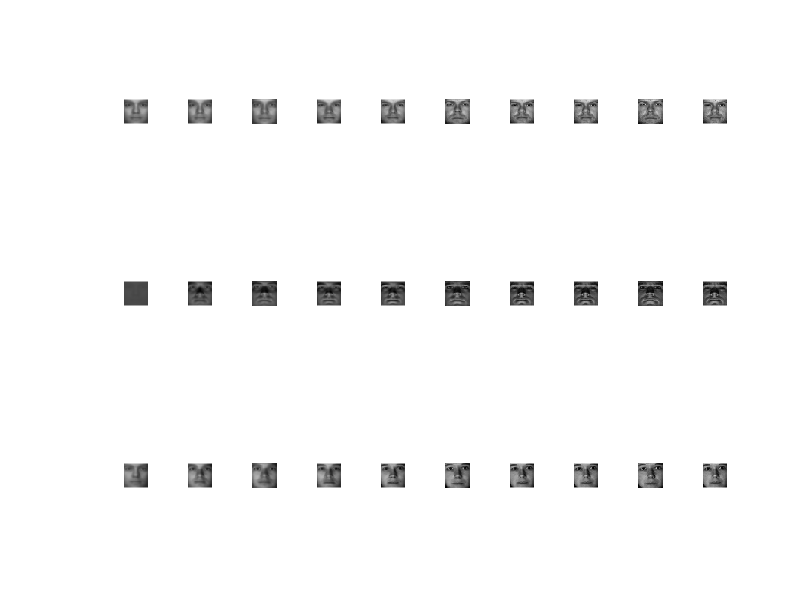

set_i = [1,1076,2043];
set_j = [2^1,2^2,2^3,2^4,2^5,2^6,2^7,2^8,2^9,2^10];

figure;

for i = 1:3
    for e = 1:10
        subplot(3,10,(i-1)*10+e);
        %compute projection
        x = X(:,set_i(i));
        u = U(:,1:set_j(e));
        sol = zeros(1024,1);
        for j = 1:size(u,2)
            sol = sol + x'*u(:,j)*u(:,j);
        end
        sol = sol + M_avg(set_i(i));
        sol = reshape(sol,[32,32]);
        imshow(sol/255);
    end
end

e)

%use 25 eigenvectors
set_1 = [1,2,7];
set_2 = [2043,2044,2045];
u = U(:,1:25);

%compute difference between different people
sim_12 = zeros(3);
for i = 1:3
    for e = i:3
        %compute coefficients for image i of person 1
        %and image e of person 2
        im_1 = X(:,set_1(i));
        im_2 = X(:,set_2(e));

        c_1 = zeros(25,1);
        for j = 1:size(u,2)
            c_1(j) = im_1'*u(:,j);
        end

        c_2 = zeros(25,1);
        for j = 1:size(u,2)
            c_2(j) = im_2'*u(:,j);
        end

        sim_12(i,e) = norm(c_1-c_2);
    end
end

%compute difference between different people
sim_11 = zeros(3);
for i = 1:3
    for e = i:3
        %compute coefficients for image i of person 1
        %and image e of person 2
        im_1 = X(:,set_1(i));
        im_2 = X(:,set_1(e));

        c_1 = zeros(25,1);
        for j = 1:size(u,2)
            c_1(j) = im_1'*u(:,j);
        end

        c_2 = zeros(25,1);
        for j = 1:size(u,2)
            c_2(j) = im_2'*u(:,j);
        end

        sim_11(i,e) = norm(c_1-c_2);
    end
end

%compute difference between different people
sim_22 = zeros(3);
for i = 1:3
    for e = i:3
        %compute coefficients for image i of person 1
        %and image e of person 2
        im_1 = X(:,set_2(i));
        im_2 = X(:,set_2(e));

        c_1 = zeros(25,1);
        for j = 1:size(u,2)
            c_1(j) = im_1'*u(:,j);
        end

        c_2 = zeros(25,1);
        for j = 1:size(u,2)
            c_2(j) = im_2'*u(:,j);
        end

        sim_22(i,e) = norm(c_1-c_2);
    end
end

sim_12

sim_12 = 	1.0e+03 *

    1.0297    1.3042    0.9655
         0    1.7050    1.2501
         0         0    1.0342


sim_11

sim_11 =          0  591.0169  414.5345
         0         0  351.4316
         0         0         0


sim_22

sim_22 =          0  613.4374  281.4377
         0         0  809.3715
         0         0         0


Similarity between images are an order of magnitude larger than for images of the same subject. We can use this fact for facial recognition by comparing the projection coefficients between subjects and associating those with low difference in projection coefficients together.